# **Lung CT image segmentation**

A CT scan of 136 images in 10 times instances was given. The patient is 67-year-old.

Images were firstly extracted for all time instances. Moreover, since DICOM files were analysed, `info` were taken from the first image to obtain the features of the slices.

T = [{'0'}, {'10'}, {'20'}, {'30'}, {'40'},{'50'}, {'60'}, {'70'}, {'80'}, {'90'}];
vol = cell(length(T), 1);

for ti = 1:length(T)
    [vol{ti}, ~] = readDCMfolder(T{ti});
end

folder = ['Patient0/T_', '0', '/CT/'];
D = dir([folder, '*.dcm']);
info = dicominfo([folder, D(1).name]);

First slice at time 0 was considered to properly choose the adjustement parameter gamma. Image was firstly normalised. Thank to `imcrop `function, a ROI (Region of Interest) was chosen and kept for all the other slices. The aim was to isolate lungs only. *ROI is saved in variable RECT.mat*.

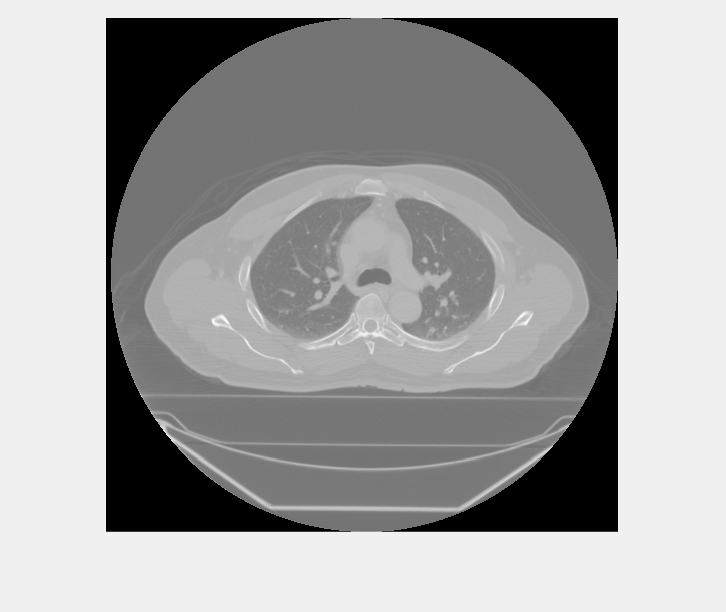

t=1;
im = vol{t}(:,:,1);

%Normalisation
max_im = max(im(:));
min_im = min(im(:));
im = (im-min_im)./(max_im-min_im);
figure
[im, RECT] = imcrop(im);

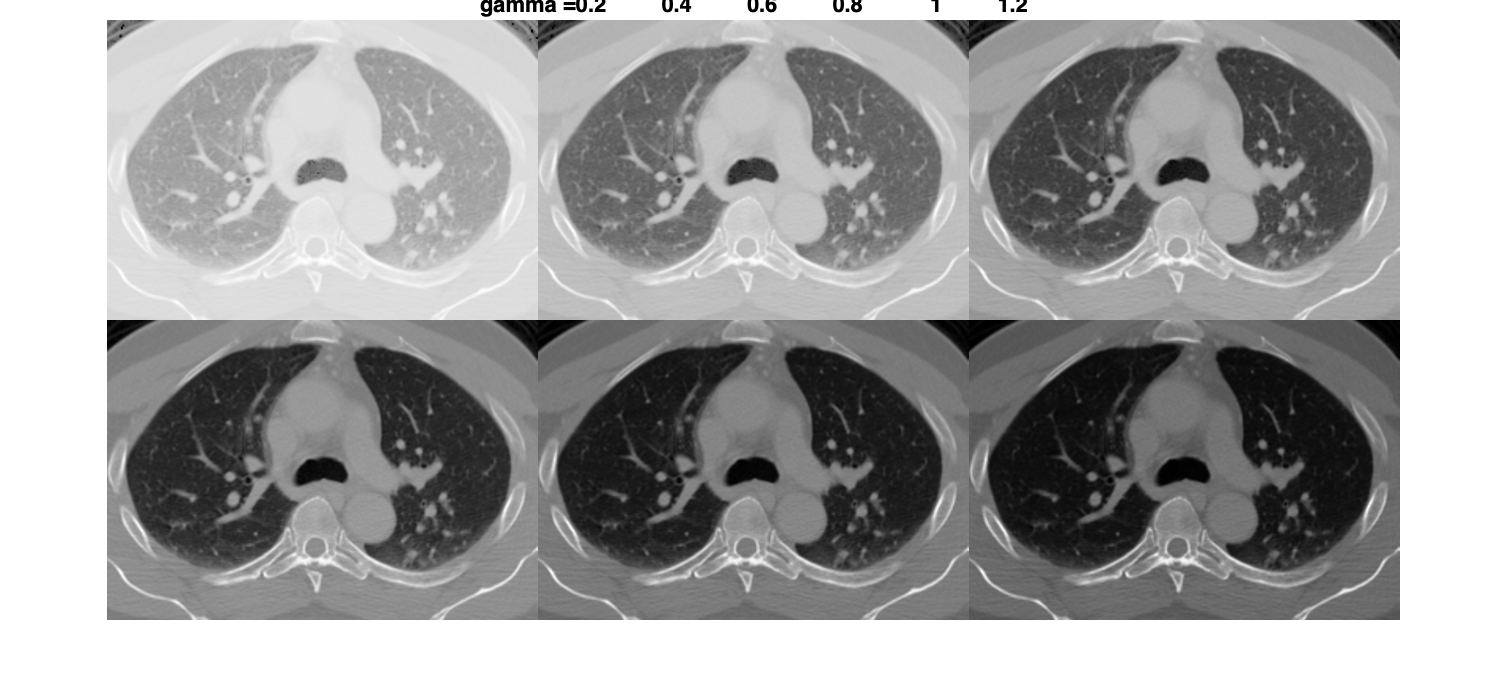

%load("ROI.mat")
%im = imcrop(im, RECT)
gamma_vect = 0.2:0.2:1.2;
LOW_IN = min(im(:));
HIGH_IN = max(im(:));
LOW_OUT = 0;
HIGH_OUT = 1;
im_adj= zeros(size(im,1),size(im,2),length(gamma_vect));
for i = 1:length(gamma_vect)
    im_adj(:,:,i) = imadjust(im, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma_vect(i));
end

figure
montage(im_adj)
title(strcat('gamma = ', num2str(gamma_vect)))

Gamma was chosen to be 0.6 because image with this adjustment is able to better enhance lungs with details in respect to the background. `getps `function was used to manually select pixels belonging to the lungs, in order to create a mask to then perform segmentation.

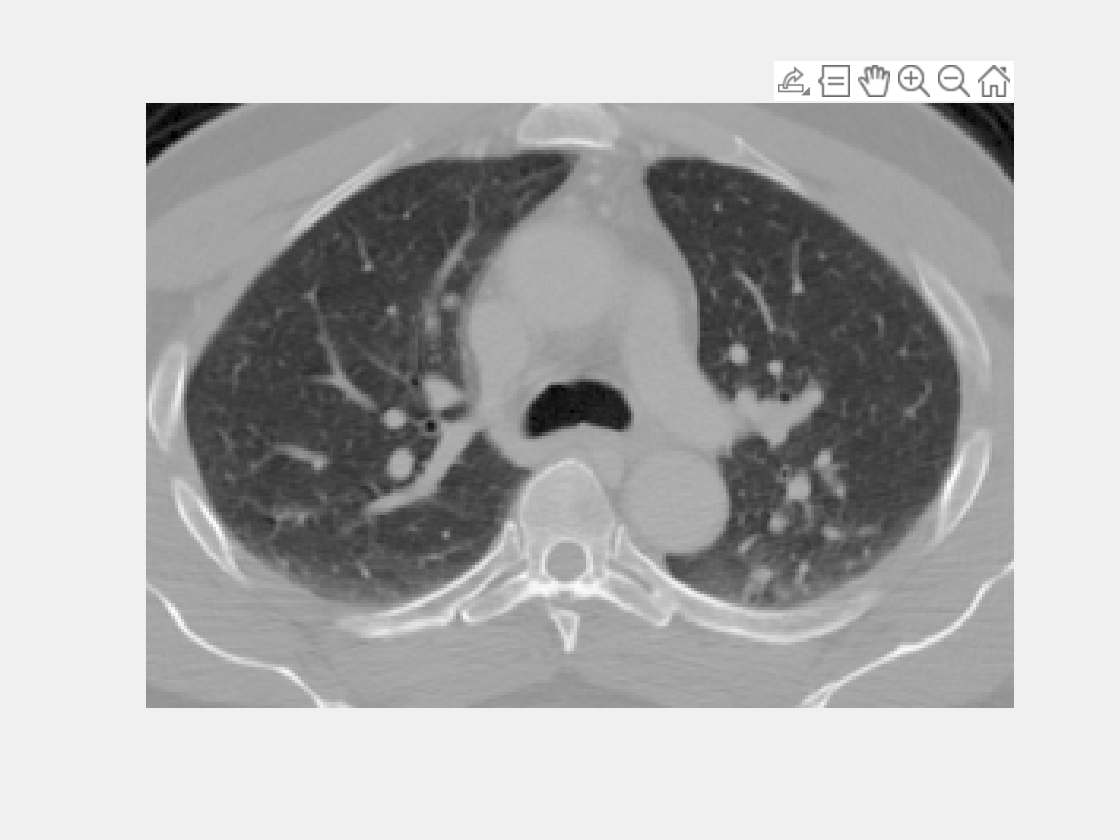

im_adj = imadjust(im, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma_vect(3));
figure, imshow(im_adj, [], 'InitialMagnification', 'fit')
[X,Y] = getpts();

Histogram of the adjusted image was plotted to choose the right threshold (0.5) for T-transformation:


$$\left\lbrace \begin{array}{ll}
\textrm{im}>0\ldotp 5 & 0\\
\textrm{im}<0\ldotp 5 & \textrm{keep}
\end{array}\right.$$


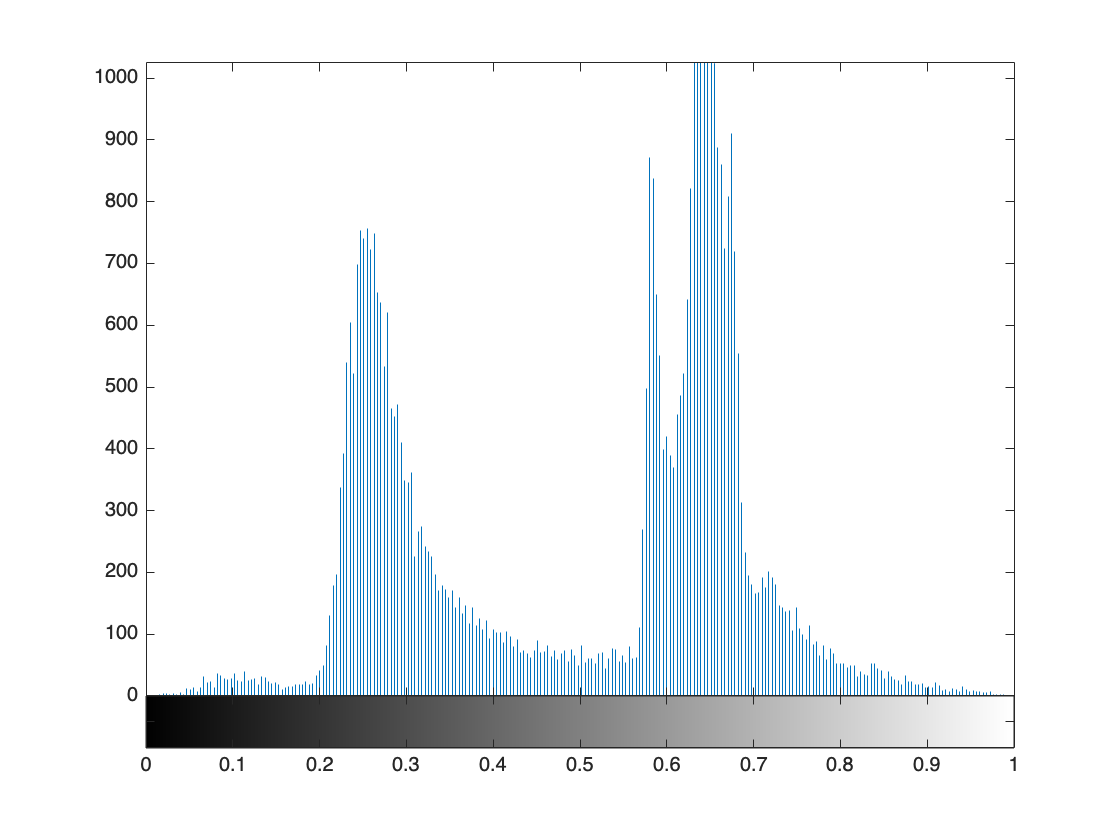

figure, imhist(im_adj)

### **All time instants **

Slices of interest were the ones containing lungs. Therefore, only the first 59 slices were taken into consideration.

Each slice was segmented by performing the normalisation, the adjustment and the conversion into binary (with `bwselect`) to obtain the mask. The image was finally multiplied by the mask.

segmented_image = cell(length(T),1);
for t=1:length(T)
    if t~=6
        im_vect = vol{t}(:,:,1:51);
    else 
        im_vect = vol{t}(:,:, 85:136);
    end 
    %bw_t = zeros(size(im,1),size(im,2),59);
    gamma=gamma_vect(3);
    for i = 1:51
        im = im_vect(:,:,i);
        im = imcrop(im, RECT);
        max_im = max(im(:));
        min_im = min(im(:));
        im = (im-min_im)./(max_im-min_im);
        LOW_IN = min(im(:));
        HIGH_IN = max(im(:));
        LOW_OUT = 0;
        HIGH_OUT = 1;
        im_adj = imadjust(im, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma);
    
        im_adj(im_adj > 0.5) = 0;
        bw = bwselect(im_adj, X, Y);
        bw = imfill(bw,"holes"); %correction of holes
        segmented_image{t}(:,:,i) = im.*single(bw);
        %bw_t(:,:,i) = single(bw);
    end
end 

For each segmented slice, cross-sectional area over axial slices was calculated. Since area of lungs is usually different from left to right, they were plotted individually. As it can be seen from the graph below, left lung shows a smaller overall area due to the presence of the heart; the trend is similar.

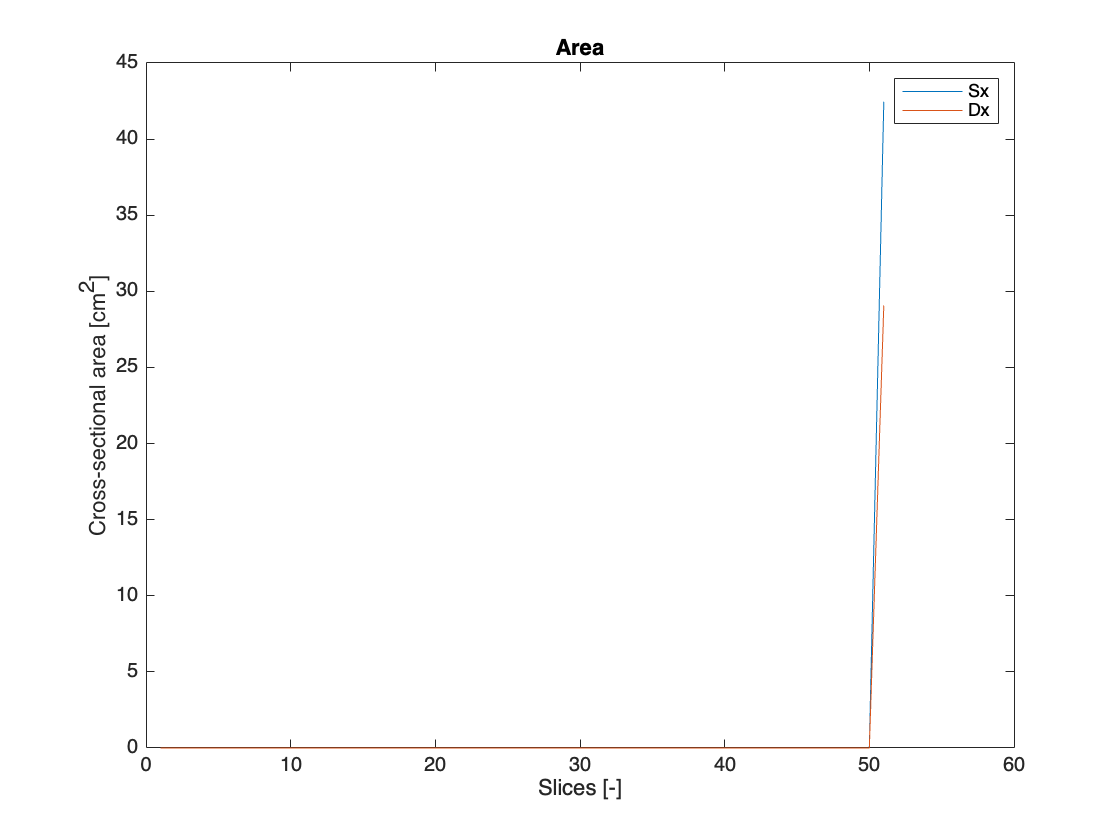

t=1;
slice = segmented_image{t}(:,:,i);
        AreaLungsPixels = regionprops(logical(slice), 'Area');
        AreaLungsPixels = struct2table(AreaLungsPixels);
        spacingx = 0.976;
        spacingy = 0.976;
        spacingz = 2.5;
        unitar = spacingx*spacingy;
        AreaSx_as(i) = (AreaLungsPixels.Area(2)*unitar)*1e-2;
        AreaDx_as(i) = (AreaLungsPixels.Area(1)*unitar)*1e-2;
        figure, plot(1:51, AreaSx_as, 1:51, AreaDx_as)
        legend('Sx', 'Dx')
        title('Area')
        xlabel('Slices [-]')
        ylabel('Cross-sectional area [cm^2]')

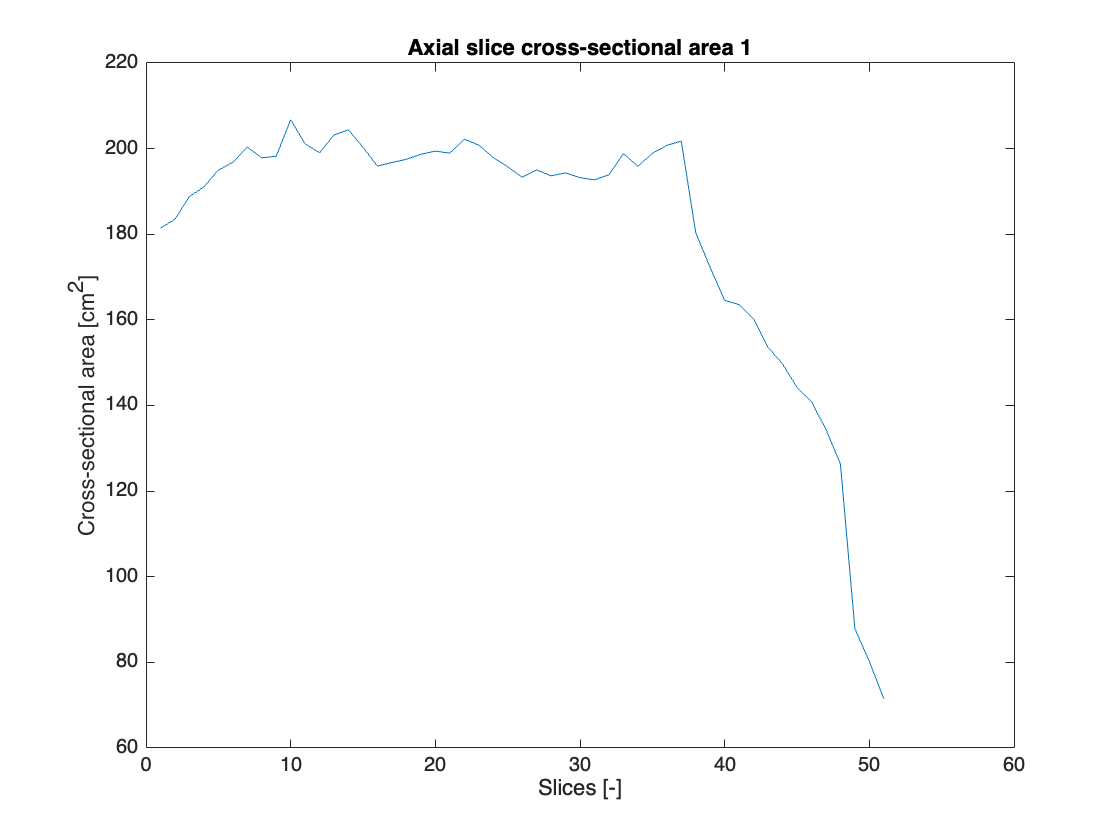

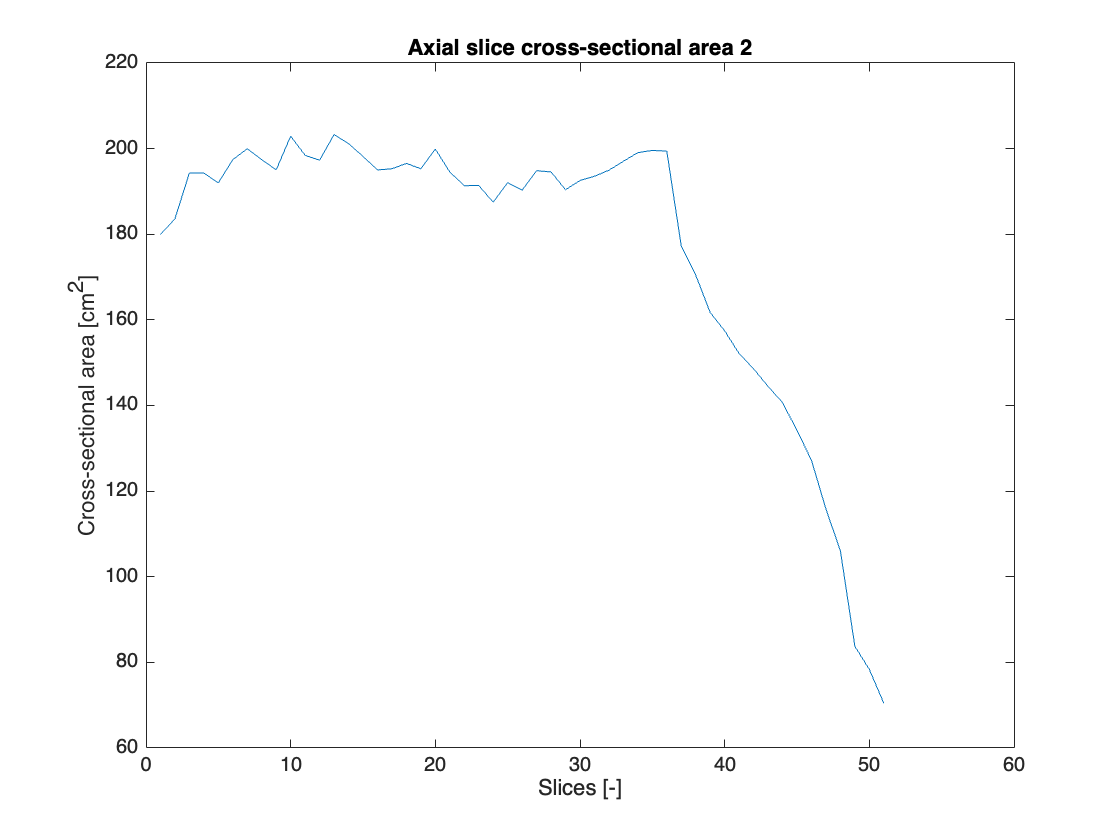

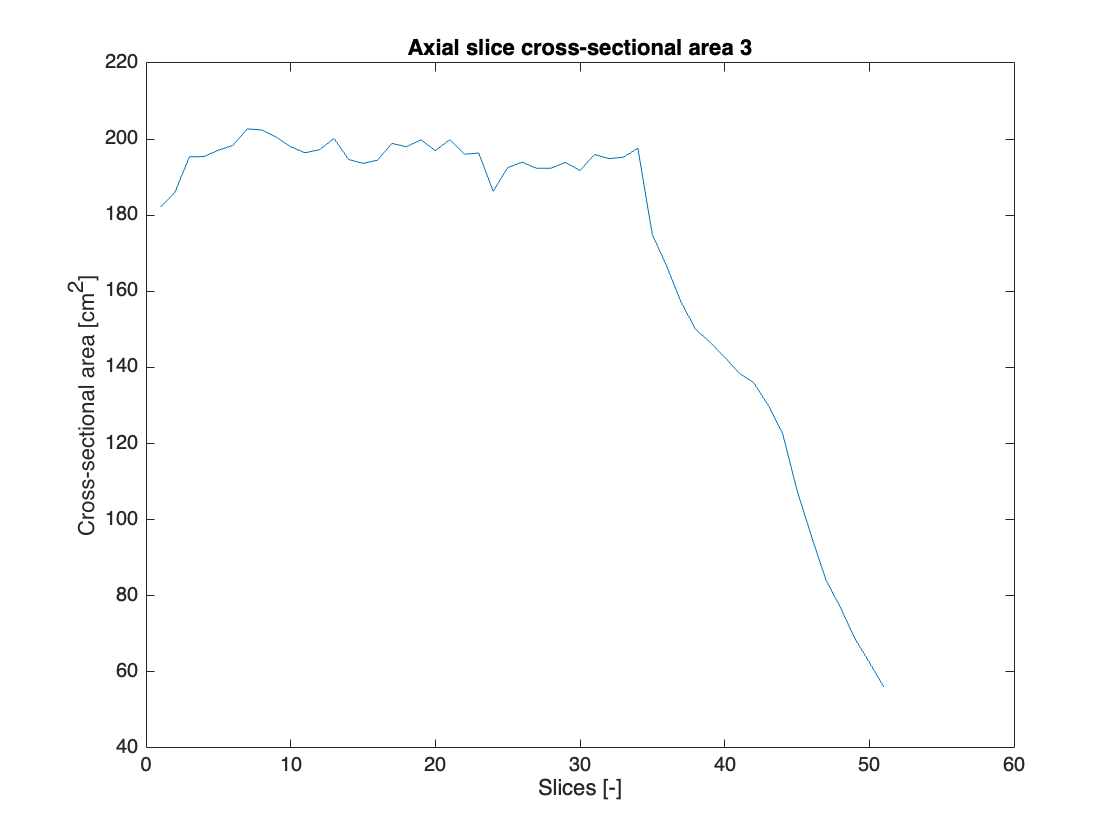

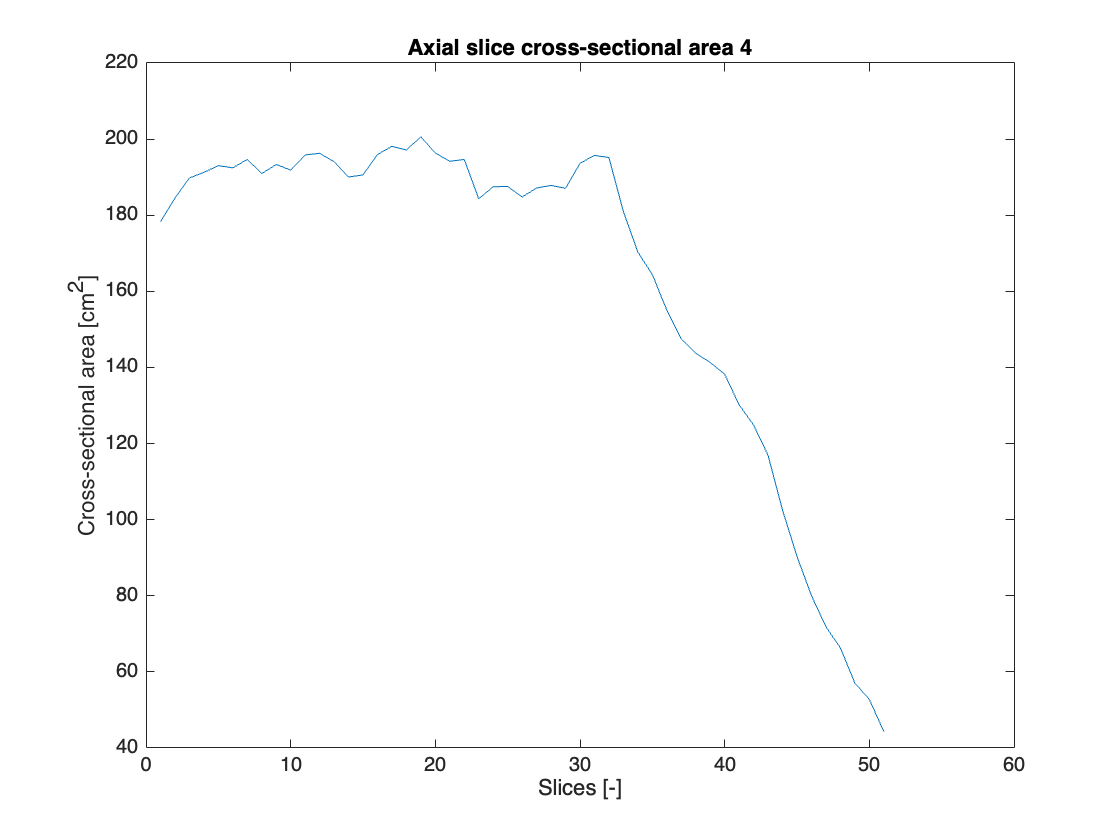

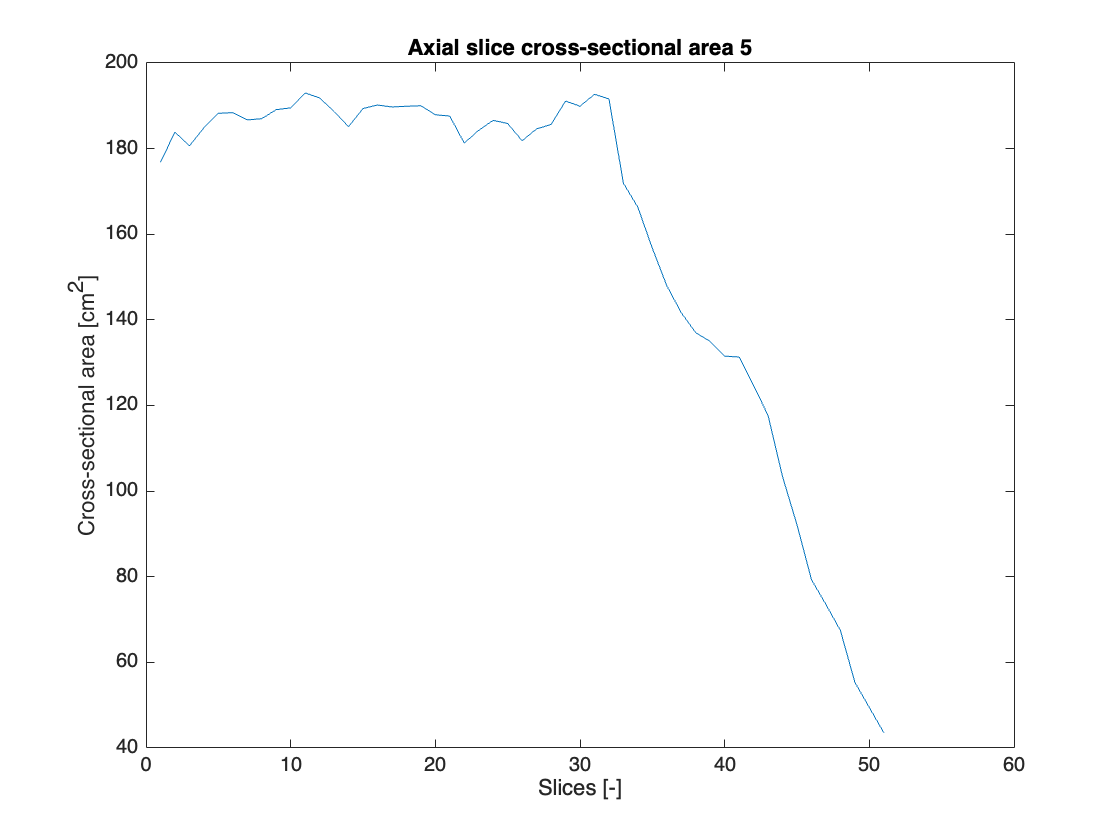

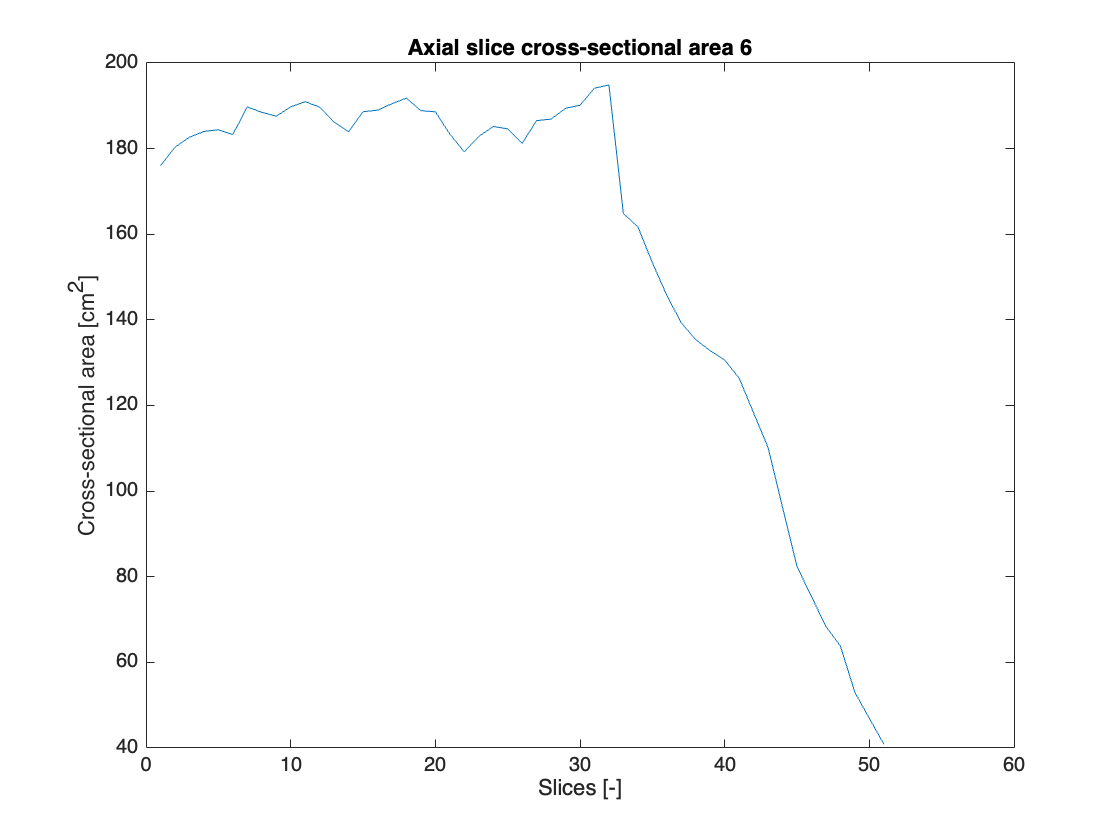

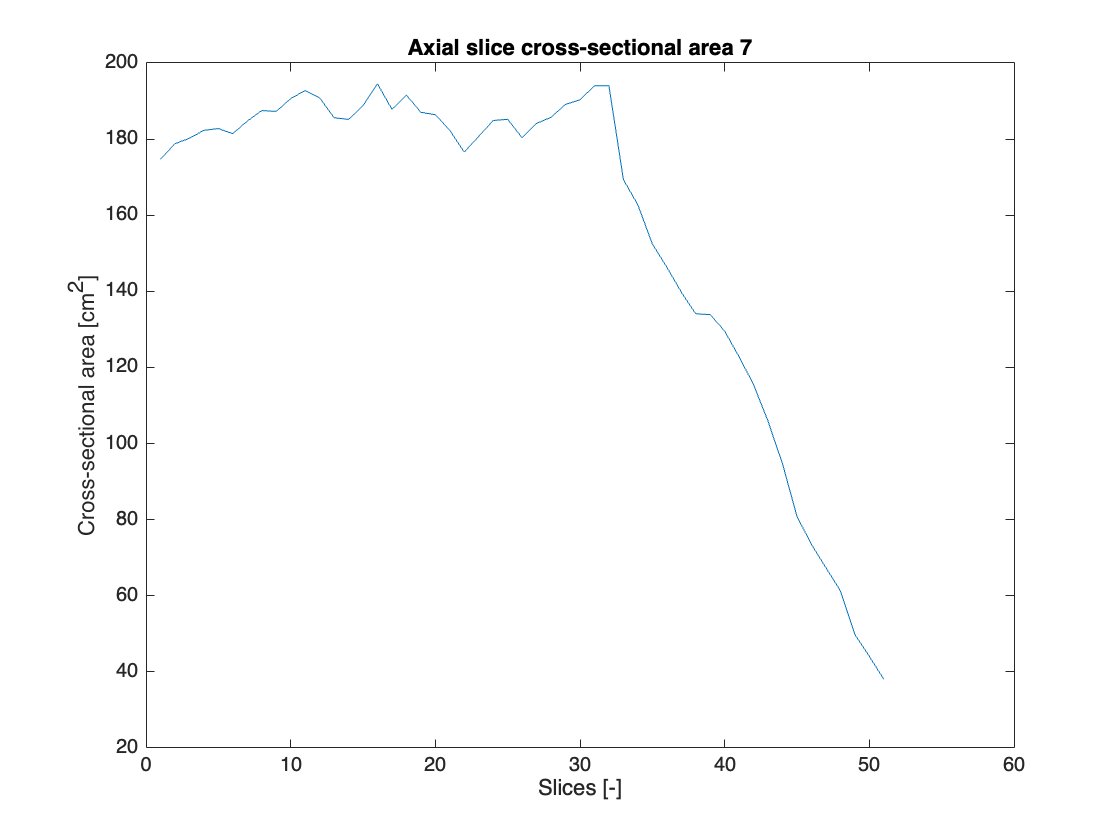

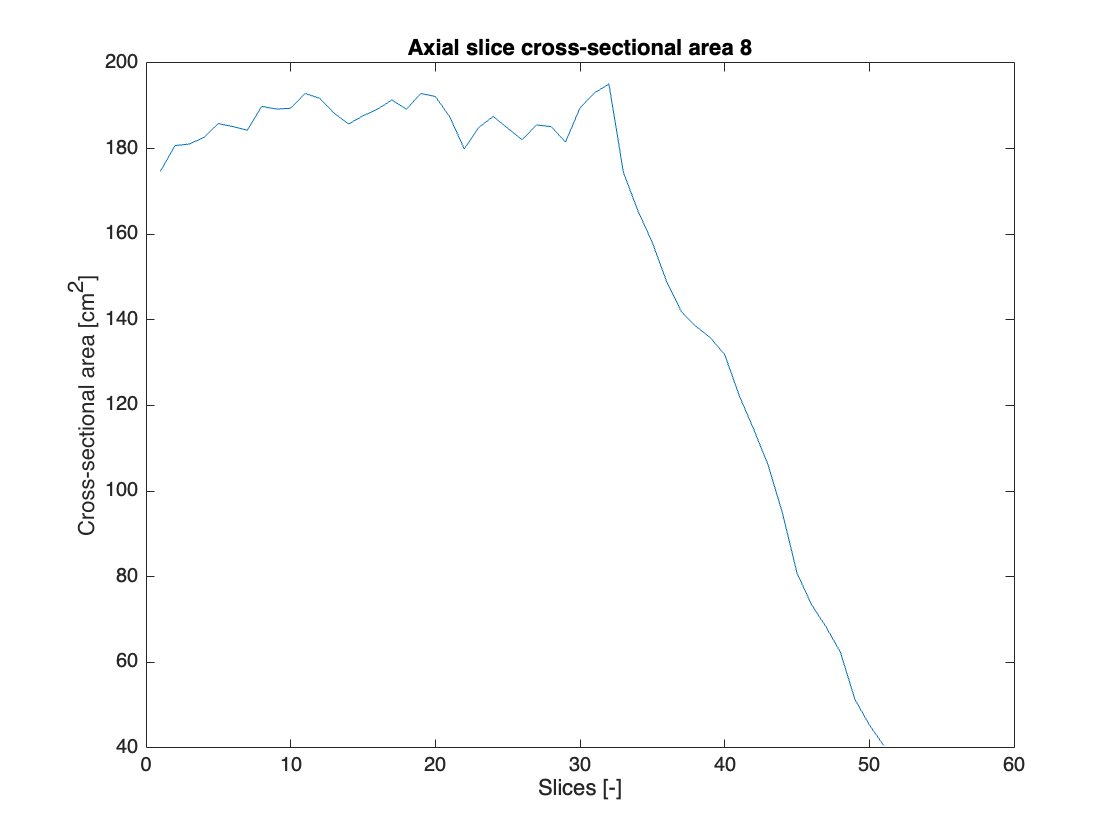

        saveas(gcf(),['AreaSxDx_', num2str(t)],'fig');

for t=1:length(T)    
    for i = 1:51
        slice = segmented_image{t}(:,:,i);
        AreaLungsPixels = regionprops(logical(slice), 'Area');
        AreaLungsPixels = struct2table(AreaLungsPixels);
        spacingx = 0.976;
        spacingy = 0.976;
        spacingz = 2.5;
        unitar = spacingx*spacingy;
        Area_tot{t}(i)=(sum(AreaLungsPixels.Area)*unitar)*1e-2;
    end 
        figure, plot(1:51, Area_tot{t});
        title(['Axial slice cross-sectional area ', num2str(t)])
        xlabel('Slices [-]')
        ylabel('Cross-sectional area [cm^2]')
        %saveas(gcf(),['Areatot_', num2str(t)],'fig');
end 

%disp(['Area at slice 20 is: ', num2str(AreaSx_as(20)+AreaDx_as(20)), ' cm^2'])

## Coronal - sectional Area (XZ)

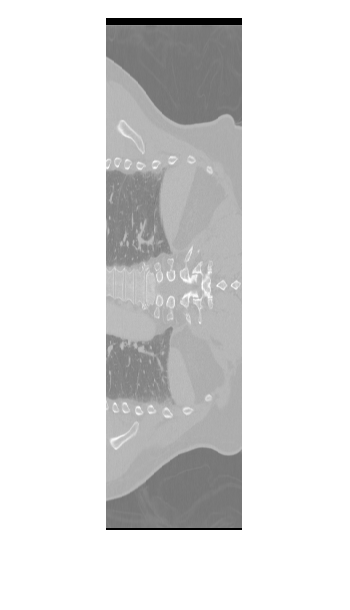

im_XZ = squeeze(vol{1}(290,:,:));
%Normalization
max_im = max(im_XZ(:));
min_im = min(im_XZ(:));
im_XZ = (im_XZ-min_im)./(max_im-min_im);
figure
[im_XZ, RECT] = imcrop(im_XZ);

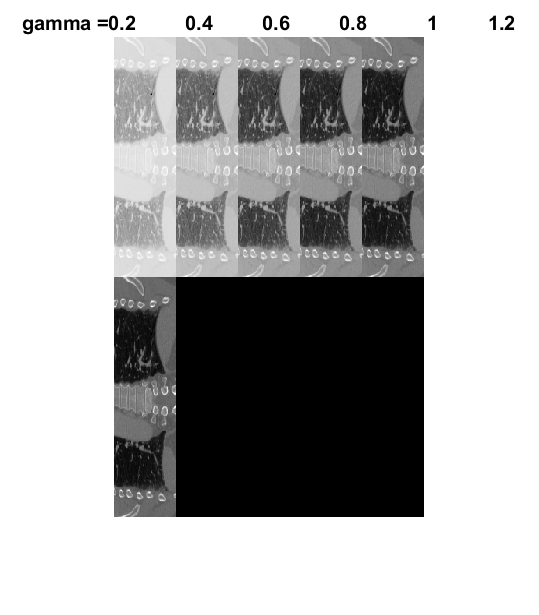

%load("ROI.mat")
%im = imcrop(im, RECT)
gamma_vect = 0.2:0.2:1.2;
LOW_IN = min(im_XZ(:));
HIGH_IN = max(im_XZ(:));
LOW_OUT = 0;
HIGH_OUT = 1;
im_adj_XZ= zeros(size(im_XZ,1),size(im_XZ,2),length(gamma_vect));
for i = 1:length(gamma_vect)
    im_adj_XZ(:,:,i) = imadjust(im_XZ, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma_vect(i));
end

figure
montage(im_adj_XZ)
title(strcat('gamma = ', num2str(gamma_vect)))

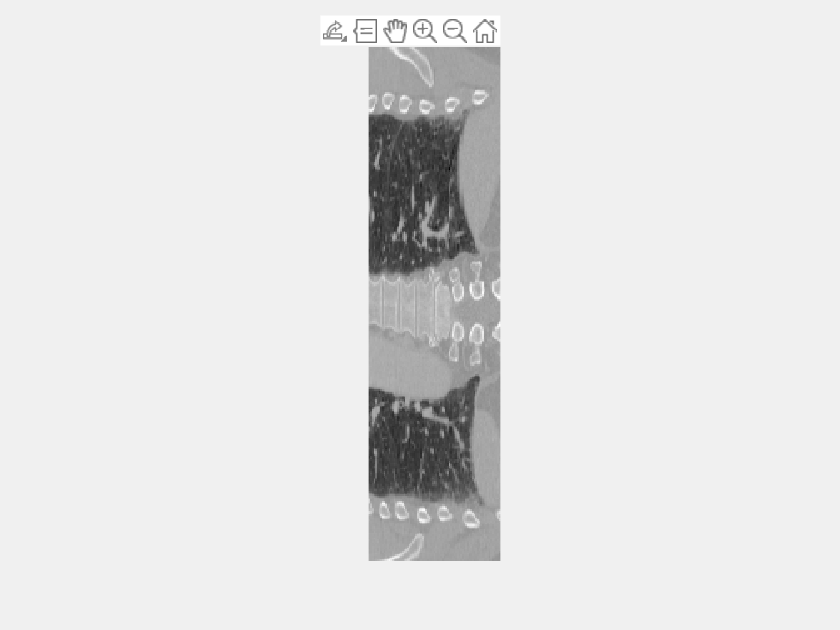

im_adj_XZ= imadjust(im_XZ, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma_vect(3));
figure, imshow(im_adj_XZ, [], 'InitialMagnification', 'fit')
[X,Z] = getpts();

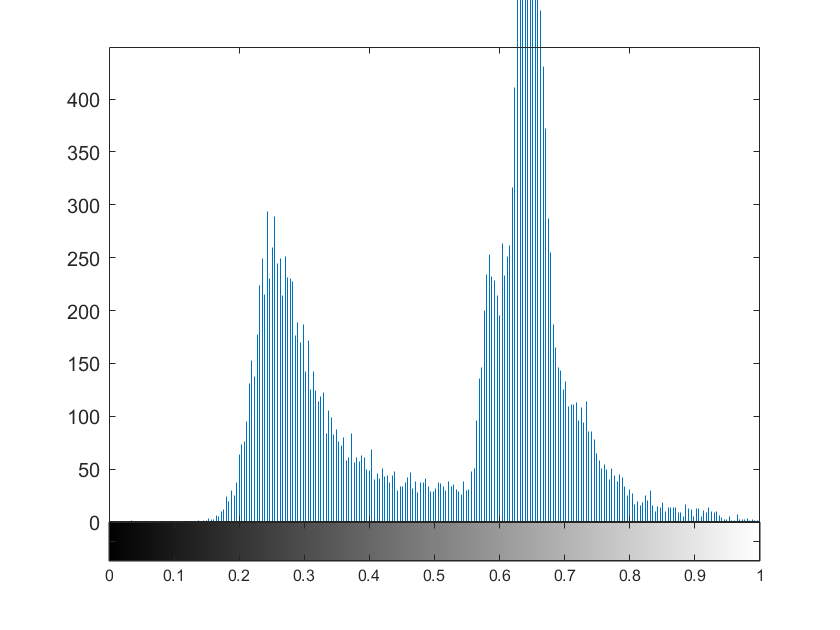

figure, imhist(im_adj_XZ)

segmented_image_XZ = cell(length(T),1);
for t = 1: length(T)
    if t~=6
        im_vect_XZ = vol{t}(180:315,:,1:51);
    else 
        im_vect_XZ = vol{t}(180:315,:, 85:136);
    end 

    for i = 1:135
        im_XZ = squeeze(im_vect_XZ(i,:,:));
        im_XZ = imcrop(im_XZ, RECT);
        max_im = max(im_XZ(:));
        min_im = min(im_XZ(:));
        im_XZ = (im_XZ-min_im)./(max_im-min_im);
        LOW_IN = min(im_XZ(:));
        HIGH_IN = max(im_XZ(:));
        LOW_OUT = 0;
        HIGH_OUT = 1;
        im_adj_XZ = imadjust(im_XZ, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma);
    
        im_adj_XZ(im_adj_XZ > 0.5) = 0;
        bw_XZ = bwselect(im_adj_XZ, X, Z);
        bw_XZ = imfill(bw_XZ,"holes"); %correction of holes
        segmented_image_XZ{t}(i,:,:) = im_XZ.*single(bw_XZ);
    end 
end

Error using parseInputsOverTwo
Expected input number 2, RECT, to be a vector.

Error in images.internal.crop.parseInputsOverTwo>validateRectangle (line 173)
validateattributes(rect,{'numeric'},{'real','vector'}, ...

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('images.internal.crop.parseInputsOverTwo', '/Applications/MATLAB_R2022b.app/toolbox/images/images/+images/+internal/+crop/parseInputsOverTwo.m', 54)" style="font-weigh

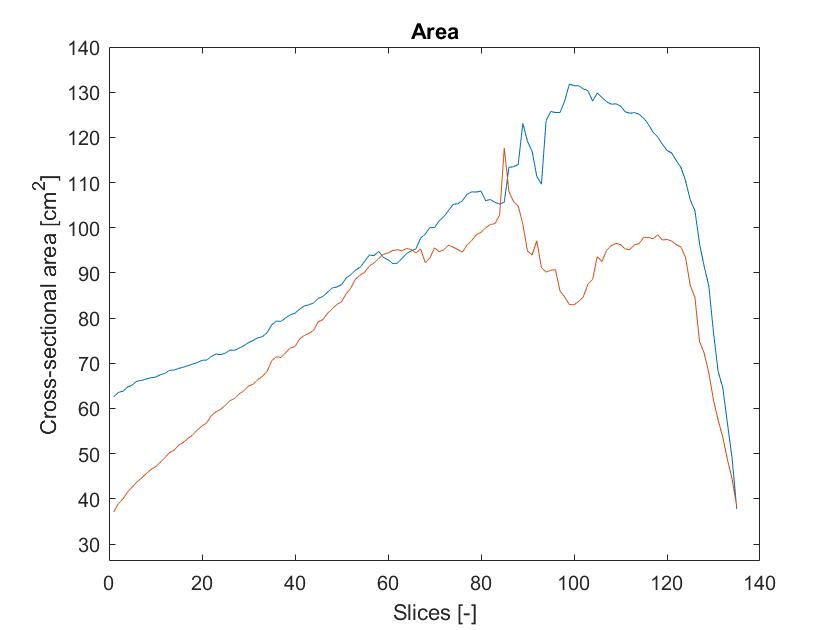

for i = 1:135
    slice_XZ = segmented_image_XZ(i,:,:);
    AreaLungsPixels_XZ = regionprops(logical(slice_XZ), 'Area');
    AreaLungsPixels_XZ = struct2table(AreaLungsPixels_XZ);
    spacingx = 0.976;
    spacingy = 0.976;
    spacingz = 2.5;
    unitar_XZ = spacingx*spacingz;
    %AreaLungsPixels_XZ_sum=sum(AreaLungsPixels_XZ.Area);
    %Area_tot_XZ(i)=(AreaLungsPixels_XZ_sum*unitar_XZ)*1e-2;
    AreaSx_cs(i) = (AreaLungsPixels_XZ.Area(1)*unitar_XZ)*1e-2;
    AreaDx_cs(i) = (AreaLungsPixels_XZ.Area(2)*unitar_XZ)*1e-2;
end

figure, plot(1:135, AreaSx_cs, 1:135, AreaDx_cs)
title('Area')
xlabel('Slices [-]')
ylabel('Cross-sectional area [cm^2]')

## Volume at t=0


%VOLUME T=0

volLungsPixels = regionprops3(logical(segmented_image),"volume");

spacingx = 0.976;
spacingy = 0.976;
spacingz = 2.5*1e-6;
unitvol = spacingx*spacingy*spacingz;

volLungs = volLungsPixels.Volume(1)*unitvol + volLungsPixels.Volume(2)*unitvol;
